%% Projeto Computacional - Acoplamento de Geometria Refinada com Solver FEM 3D
clear
close all
clc


## 1. Parâmetros físicos e geométricos

% Iniciar o cronómetro global para medir a performance
tic;

k_gelo = 2.22;          % Condutividade térmica [W/(m.K)]
qdot = 0;               % Fonte interna [W/m^3]
rho_gelo = 917;         % Densidade [kg/m^3]
cp_gelo = 2100;         % Calor específico [J/(kg.K)]

T_meio = 20;            % Temperatura do meio exterior [°C]
h = 15;                 % Coeficiente de convecção [W/(m^2*K)]

T_inicial = -10;        % Temperatura inicial do gelo [°C]
Lx = 0.5;               % Meio cubo em x [-0.5 a 0.5 no total]
Ly = 0.5;               % Meio cubo em y [-0.5 a 0.5 no total]
Lz = 1.0;               % Altura total [0 a 1]


## 2. Geração da malha refinada e simétrica 


model = createpde();
geo = multicuboid(0.5, 0.5, 1);
model.Geometry = geo;

% IDs da face, arestas e vértices superiores
topFace = 2;
topEdges = [7];
topVertices = [6 7];

% Gerar a malha refinada no topo
mesh = generateMesh(model, ...
    'Hmax', 0.15, ...
    'Hmin', 0.04, ...
    'Hface', {topFace, 0.08}, ...
    'Hedge', {topEdges, 0.06}, ...
    'Hvertex', {topVertices, 0.04}, ...
    'Hgrad', 1.5, ...
    'GeometricOrder', 'linear');

nodes = mesh.Nodes;
elements = mesh.Elements;

N = size(nodes,2);
E = size(elements,2);

% Deslocar para o quadrante correto x=[0,0.5], y=[0,0.5], z=[0,1]
nodes(1,:) = nodes(1,:) + 0.25;
nodes(2,:) = nodes(2,:) + 0.25;
nodes(3,:) = nodes(3,:) - min(nodes(3,:));
nodes(3,:) = nodes(3,:) / (max(nodes(3,:)) - min(nodes(3,:)));

nodesAll = zeros(3,4*N);
elementsAll = zeros(size(elements,1),4*E);

for q = 1:4
    switch q
        case 1
            sx = 1;  sy = 1;
        case 2
            sx = -1; sy = 1;
        case 3
            sx = 1;  sy = -1;
        case 4
            sx = -1; sy = -1;
    end

    newNodes = nodes;
    newNodes(1,:) = sx*nodes(1,:);
    newNodes(2,:) = sy*nodes(2,:);

    idxN = (q-1)*N + (1:N);
    idxE = (q-1)*E + (1:E);

    nodesAll(:,idxN) = newNodes;
    elementsAll(:,idxE) = elements + (q-1)*N;
end

% Unir nós coincidentes nas fronteiras de simetria
tol = 1e-10;
[uniqueNodes,~,ic] = unique(round(nodesAll'/tol)*tol,'rows');

% Mapeamento para as variáveis padrão do solver do 2º código
coord = uniqueNodes;                     % Dimensão: [N_nos x 3]
elem = reshape(ic(elementsAll), size(elementsAll))'; % Dimensão: [Ne x 4]

N_nos = size(coord, 1);
Ne = size(elem, 1);


## 3. Inicialização das matrizes globais


K = zeros(N_nos, N_nos);
M = zeros(N_nos, N_nos);
F = zeros(N_nos, 1);


## 4. Assemblagem FEM 3D


fprintf('A realizar a assemblagem FEM para %d nós e %d elementos...\n', N_nos, Ne);

A realizar a assemblagem FEM para 830 nós e 3328 elementos...


for e = 1:Ne
    nos = elem(e,:);

    xe = coord(nos,1);
    ye = coord(nos,2);
    ze = coord(nos,3);

    P = [ones(4,1), xe, ye, ze];
    Ve = abs(det(P))/6;

    % Coeficientes das funções de forma
    C = P\eye(4);

    % Matriz das derivadas
    B = C(2:4,:);

    % Matriz de condução térmica
    Ke = k_gelo * Ve * (B' * B);

    % Matriz de massa térmica
    Me = (rho_gelo * cp_gelo * Ve / 20) * ...
        [2 1 1 1;
         1 2 1 1;
         1 1 2 1;
         1 1 1 2];

    % Vetor de fontes térmicas
    fe = (qdot * Ve / 4) * ones(4,1);

    % Assemblagem global
    K(nos,nos) = K(nos,nos) + Ke;
    M(nos,nos) = M(nos,nos) + Me;
    F(nos) = F(nos) + fe;
end

%% 5. Condições de fronteira - Convecção apenas na face superior (z = Lz)
K_conv = zeros(N_nos, N_nos);
F_conv = zeros(N_nos, 1);

% Construção de todas as faces triangulares dos tetraedros
faces = [
    elem(:,[1 2 3]);
    elem(:,[1 2 4]);
    elem(:,[1 3 4]);
    elem(:,[2 3 4])
];

faces = sort(faces, 2);
[faces_unicas,~,ic] = unique(faces, 'rows');
contagem = accumarray(ic, 1);

% Faces exteriores (aparecem apenas uma vez)
faces_exteriores = faces_unicas(contagem == 1, :);
N_faces = size(faces_exteriores, 1);
n_faces_conveccao = 0;

tol_geom = 1e-5;

for f = 1:N_faces
    nos = faces_exteriores(f,:);

    p1 = coord(nos(1),:);
    p2 = coord(nos(2),:);
    p3 = coord(nos(3),:);

    % Verificar se os 3 nós pertencem à face superior (z = Lz = 1.0)
    if abs(p1(3) - Lz) < tol_geom && abs(p2(3) - Lz) < tol_geom && abs(p3(3) - Lz) < tol_geom
        n_faces_conveccao = n_faces_conveccao + 1;

        Af = 0.5 * norm(cross(p2 - p1, p3 - p1));

        Kf = (h * Af / 12) * [
            2 1 1;
            1 2 1;
            1 1 2
        ];

        Ff = (h * T_meio * Af / 3) * ones(3,1);

        K_conv(nos,nos) = K_conv(nos,nos) + Kf;
        F_conv(nos) = F_conv(nos) + Ff;
    end
end

fprintf('Número total de faces exteriores: %d\n', N_faces);

Número total de faces exteriores: 976


fprintf('Faces com convecção ativa no topo (z = %.1f): %d\n', Lz, n_faces_conveccao);

Faces com convecção ativa no topo (z = 1.0): 332


## 6. Resolução temporal - Crank Nicolson


dt = 5;
t_final = 50000;%[s]
Nt = round(t_final/dt);

T0_vec = T_inicial * ones(N_nos, 1);
T = T0_vec;

K_total = K + K_conv;
F_total = F + F_conv;

A = M + (dt/2) * K_total;
D = M - (dt/2) * K_total;

[L,U] = lu(A);

T_hist = zeros(N_nos, Nt+1);
T_hist(:,1) = T;

fprintf('A executar a simulação temporal por Crank-Nicolson (%d passos)...\n', Nt);

A executar a simulação temporal por Crank-Nicolson (10000 passos)...


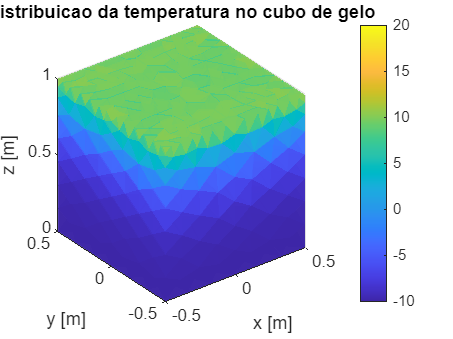

for n = 1:Nt
    rhs = D * T + dt * F_total;
    T = U \ (L \ rhs);
    T_hist(:,n+1) = T;
end

%% 7. Temperatura média de cada elemento

T_elem = zeros(Ne, 1);
for e = 1:Ne
    nos = elem(e,:);
    T_elem(e) = mean(T(nos));
end

%% 8. Visualização da temperatura

figure;
p = tetramesh(elem, coord, T_elem);
set(p, 'EdgeColor', 'none'); % Opcional: remove as linhas de malha para melhor visualização
xlabel('x [m]');
ylabel('y [m]');
zlabel('z [m]');
title('Distribuicao da temperatura no cubo de gelo');
clim([T_inicial, T_meio]);
colorbar;
axis equal;
grid on;
view(3);

tempo_total = toc;

## 9. Resultados finais


fprintf('\n--- RESULTADOS FINAIS ---\n');


--- RESULTADOS FINAIS ---


fprintf('Número de nós: %d\n', N_nos);

Número de nós: 830


fprintf('Número de elementos: %d\n', Ne);

Número de elementos: 3328


fprintf('Temperatura mínima: %.2f °C\n', min(T));

Temperatura mínima: -9.97 °C


fprintf('Temperatura máxima: %.2f °C\n', max(T));

Temperatura máxima: 11.00 °C


fprintf('Tempo de exposição: %.2f segundos\n', t_final);

Tempo de exposição: 50000.00 segundos


fprintf('Tempo total de execução do script: %.2f segundos\n', tempo_total);

Tempo total de execução do script: 23.08 segundos
